### **Aufgabe 3 b)**

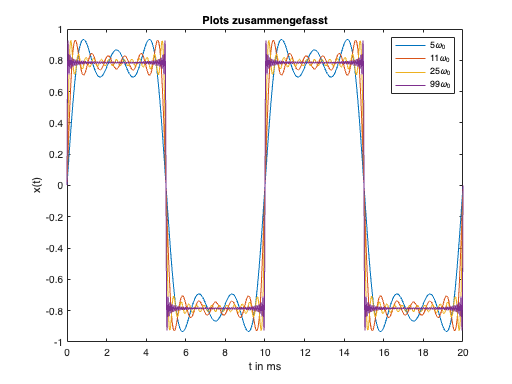

clear;

% vorgegebene Werte in ms
FS = 100;
TS = 1 / FS;
t = 0:TS:20;
TP = 10;
omega0 = (2 * pi) / TP;

factors = [2, 5, 12, 49];

for f = 1:1:length(factors)
    % Berechnung
    numbers = 0:1:factors(f);
    result = zeros(1, length(t));
    for i = 1:1:length(t) 
        for j = 1:1:length(numbers)
            result(i) = result(i) + ((1 / (2 * numbers(j) + 1)) * sin((2 * numbers(j) + 1) * omega0 * t(i)));
        end
    end

    % Plotting
    xlabel("t in ms");
    ylabel("x(t)")
    plot(t, result);
    hold on;
end
xlabel("t in ms");
ylabel("x(t)");
title("Plots zusammengefasst");
legend("5{\omega}_{0}", "11{\omega}_{0}", "25{\omega}_{0}", "99{\omega}_{0}");
hold off;

% erneute Berechnung zur Darstellung in einzelnen Plots
for f = 1:1:length(factors)
    % Berechnung
    numbers = 0:1:factors(f);
    result = zeros(1, length(t));
    for i = 1:1:length(t) 
        for j = 1:1:length(numbers)
            result(i) = result(i) + ((1 / (2 * numbers(j) + 1)) * sin((2 * numbers(j) + 1) * omega0 * t(i)));
        end
    end

    % Plotting
    xlabel("t in ms");
    ylabel("x(t)")
    subplot(2, 2, f);
    plot(t, result);
    title(factors(f) * 2 + 1 + "{\omega}_{0}");
end

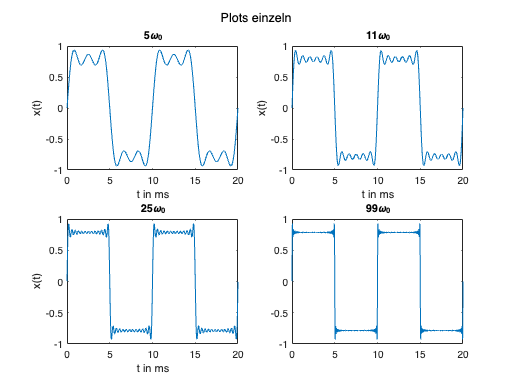

sgtitle("Plots einzeln");

ggf. muss MATLAB neu gestartet werden, um die Plots richtig laden zu können

Der Zoom kann bei den kleineren Plots außerdem hilfreich sein.